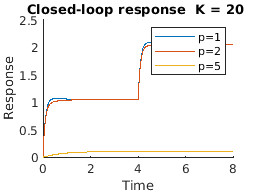

% PES1UG20EC083 Jacob V Sanoj
% CS Q2
clc
close all;

p1 = 1; p2 = 2; p3 = 5;

k1=20; k2=100;

num1_1 = 1;
den1_1 = [1,11+p1,k1];
den1_2 = [1,11+p2,k1];
den1_3 = [1,11+p3,k1];

num2_1 = [11,k1];
den2_1 = [1,11+p1,k1];
den2_2 = [1,11+p2,k1];
den2_3 = [1,11+p3,k1];

fun1_1 = tf(num1_1,den1_1);
fun1_2 = tf(num1_1,den1_2);
fun1_3 = tf(num1_1,den1_3);

fun2_1 = tf(num2_1,den2_1);
fun2_2 = tf(num2_1,den2_2);
fun2_3 = tf(num2_1,den2_3);

t = 0:0.01:8;
dist  = 1.*(t<=4) + 2.*(t>4);

Y1_1 = step(fun1_1,t);
Y2_1 = lsim(fun2_1,dist,t);

Y_1 = Y1_1+Y2_1;

Y1_2 = step(fun1_2,t);
Y2_2 = lsim(fun2_2,dist,t);

Y_2 = Y1_2+Y2_2;


Y1_3 = step(fun1_3,t);
Y2_3 = lsim(fun2_3,dist,t);

Y_3 = Y1_3+Y1_3;


% impulse reference response
figure;
hold on;
plot(t,Y_1)
plot(t,Y_2)
plot(t,Y_3)
title('Closed-loop response  K = 20 ')
xlabel('Time')
ylabel('Response')
legend('p=1','p=2','p=5')
hold off

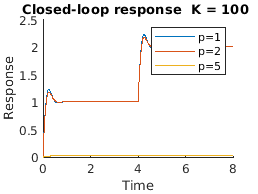


num1_1 = 1;
den1_1 = [1,11+p1,k2];
den1_2 = [1,11+p2,k2];
den1_3 = [1,11+p3,k2];

num2_1 = [11,k2];
den2_1 = [1,11+p1,k2];
den2_2 = [1,11+p2,k2];
den2_3 = [1,11+p3,k2];

fun1_1 = tf(num1_1,den1_1);
fun1_2 = tf(num1_1,den1_2);
fun1_3 = tf(num1_1,den1_3);

fun2_1 = tf(num2_1,den2_1);
fun2_2 = tf(num2_1,den2_2);
fun2_3 = tf(num2_1,den2_3);

t = 0:0.01:8;
dist  = 1.*(t<=4) + 2.*(t>4);

Y1_1 = step(fun1_1,t);
Y2_1 = lsim(fun2_1,dist,t);

Y_1 = Y1_1+Y2_1;

Y1_2 = step(fun1_2,t);
Y2_2 = lsim(fun2_2,dist,t);

Y_2 = Y1_2+Y2_2;


Y1_3 = step(fun1_3,t);
Y2_3 = lsim(fun2_3,dist,t);

Y_3 = Y1_3+Y1_3;


% impulse reference response
figure;
hold on;
plot(t,Y_1)
plot(t,Y_2)
plot(t,Y_3)
title('Closed-loop response  K = 100 ')
xlabel('Time')
ylabel('Response')
legend('p=1','p=2','p=5')
hold off